# Battery Charging Model

This live script models the charging behavior of a lithium-ion battery using an RC (resistor-capacitor) circuit approximation. The parameters are based on the Panasonic NCA103450 cell. The script calculates voltage, current, and power over time, and visualizes each with a plot.

## Clear Workspace

clear , clc, close all;

##  Define Constants 

These values are estimated to give a realistic time constant for charging. You can modify R and C to simulate different battery conditions.

V_max = 4.2;      % Maximum charging voltage (Volts)
R = 0.25;         % Equivalent resistance (Ohms)
C = 11,520;       % Equivalent capacitance (Farads)

C = 11

## Set up Time Vector 

Time resolution can be adjusted to smooth curves in the plots 

tau = R * C;            % Time constant (tau) 
t_end = 5 * tau;        % Total simulation time (~99% charge)
t = 0:0.01:t_end;       % Time vector with 0.01-second intervals

## Calculate Voltage over Time

Voltage is computed using the exponential charging equation

V_t = ComputeVoltage(V_max, tau, t);   

## Calculate Current over Time

 Current is calculated as an exponential decay function

I_t = ComputeCurrent(V_max, R, tau, t);    

## Calculate Instantaneous Power over Time

 Power is calculated as the pointwise product of voltage and current

P_t = ComputePower(V_t, I_t)

P_t =          0    0.2552    0.5076    0.7573    1.0042    1.2484    1.4900    1.7288    1.9651    2.1987    2.4297    2.6582    2.8841    3.1075    3.3284    3.5468    3.7627    3.9762    4.1873    4.3960    4.6023    4.8062    5.0078    5.2071    5.4041    5.5988    5.7912    5.9814    6.1694    6.3552    6.5388    6.7202    6.8995    7.0766    7.2517    7.4247    7.5955    7.7644    7.9312    8.0960    8.2587    8.4195    8.5784    8.7352    8.8902    9.0432    9.1944    9.3436    9.4910    9.6365


## Graph Voltage vs. Time

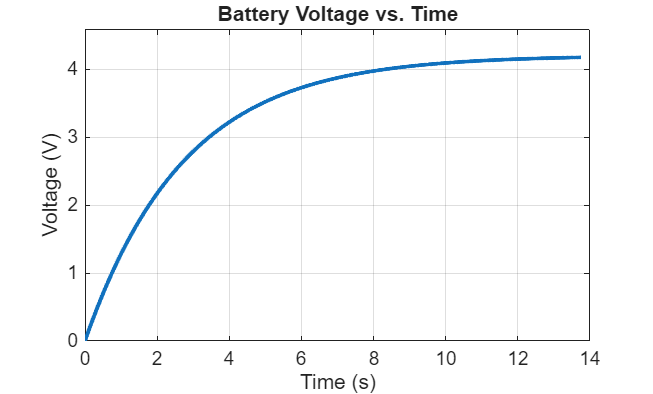

PlotVoltage(t, V_t);

## Graph Current vs. Time

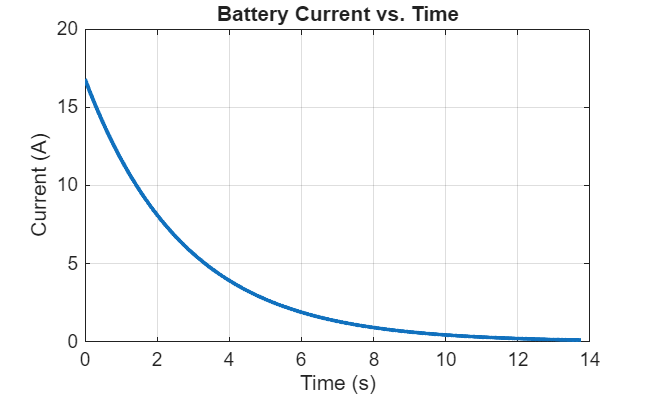

PlotCurrent(t, I_t);

## Graph Power vs. Time

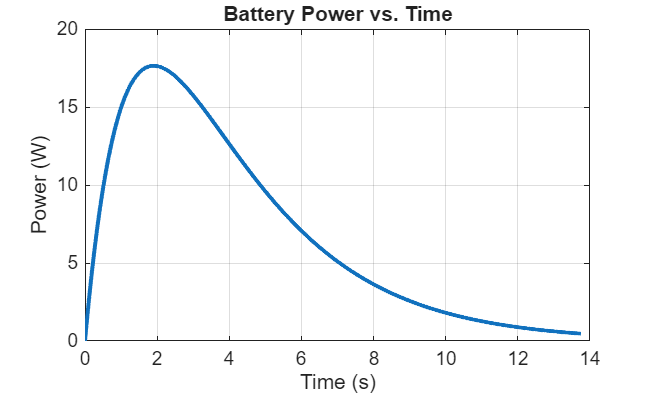

PlotPower(t, P_t);